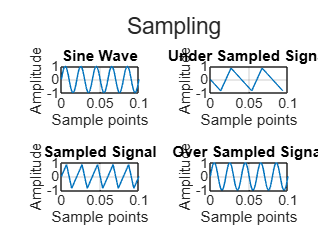

clc; 
clf;
close all;
clear all;
fm=input('Enter frequency: '); 
cyc=input('Enter no. cycles: '); 
t=0:(1/(fm*fm)):cyc/fm;
amplitude=sin(2*pi*fm*t);
fs_1=1.5*fm; 
fs_2=3*fm;
fs_3=20*fm;
t_1=0:(1/(fs_1)):cyc/fm; 
t_2=0:(1/(fs_2)):cyc/fm;
t_3=0:(1/(fs_3)):cyc/fm; 
amp_1=sin(2*pi*fm*t_1);
amp_2=sin(2*pi*fm*t_2); 
amp_3=sin(2*pi*fm*t_3);
tile=tiledlayout(2,2);
title(tile, 'Sampling');
nexttile;
plot(t,amplitude);
title('Sine Wave');
xlabel('Sample points'); 
ylabel('Amplitude');
grid on;
nexttile; 
plot(t_1,amp_1);
title('Under Sampled Signal');
xlabel('Sample points');
ylabel('Amplitude');
grid on;
nexttile;
plot(t_2,amp_2);
title('Sampled Signal'); 
xlabel('Sample points');
ylabel('Amplitude');
grid on;
nexttile;
plot(t_3,amp_3);
title('Over Sampled Signal');
xlabel('Sample points');
ylabel('Amplitude');
grid on;